# Assignment-10  171EE103

We have satellite image data in 10 different files h5 ranging from named data_1.h5, data_2.h5, etc. Each file has different satellite images named as IMG_MIR,IMG_SWIR,IMG_VIS, etc captured using different sensors on the satellite at a particular time. Since the problem statement requires the application of LSTM, which requires sequential data, we will assume that the image data collected from data_1.h5 to data_10.h5 is sequential. Since, we have only 10 datapoints, we will use the data from data_1.h5 to data_9.h5 to predict data from data_10.h5. 

## Reading the data from h5 files and clustering

Here we read the image data of different sensors from the h5 files of data-1 to data-9 and use self organising map to cluster the images from each file into 5 classes. A depiction of it is shown for data-1. This is similar to assignment-7. We then seperate the data of all the files based on the class into data structures named like image_data_C1 which is for class-1. Each of these 5 will be used to predict an image which will be the predicted image of each class for data-10.

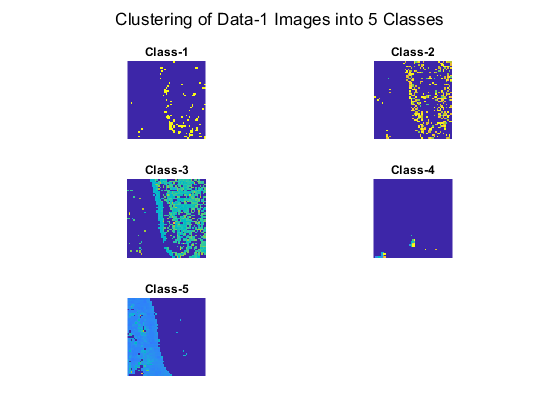

%The data structures for storing image data.
image_data_C1=[];
image_data_C2=[];
image_data_C3=[];
image_data_C4=[];
image_data_C5=[];

%Iterating for reading and clustering data from data-1 to data-9
for f = 1:9
    file = strcat(strcat('data_',num2str(f)),'.h5');
    info = h5info(file);
    dst = length(info.Datasets(:,1));
    i = 1;
    IP = [];
    for j = 1:dst
        cdataset = info.Datasets(j);
        if max(strcmp(cdataset.Name,...
                {'IMG_MIR','IMG_SWIR','IMG_TIR1',...
                'IMG_TIR2','IMG_VIS','IMG_WV'})) == 1
            attr = cdataset.Name;
            IMG = h5read(file,strcat('/',attr));
            
            crop = imcrop(IMG',[745 880 50 50]); %Cropping out NITK
            IP(i,:) = double(reshape(crop,1,[]));
            i = i+1;
            
        end
    end
    
    dim1 = 1;
    dim2 = 5;
    net = selforgmap([dim1 dim2]); %Self organizing map for clustering
    [net,tr] = train(net,IP);
    
    out = net(IP);
    
    % Here since the output from SOM is binary for it to display
    % as an image, we multiply each of the output images with IP(5)
    % which is the equivalent of projecting the clustered map on IMG_VIS
    % for displaying and storing it as an image.
    image_data_C1 = [image_data_C1 ; (out(1,:) + 0.01).*IP(5,:)];
    image_data_C2 = [image_data_C2 ; (out(2,:) + 0.01).*IP(5,:)];
    image_data_C3 = [image_data_C3 ; (out(3,:) + 0.01).*IP(5,:)];
    image_data_C4 = [image_data_C4 ; (out(4,:) + 0.01).*IP(5,:)];
    image_data_C5 = [image_data_C5 ; (out(5,:) + 0.01).*IP(5,:)];
    
    %Displaying the Clusters for data-1 for representation.
    if f ==1
        for k=1:size(out,1)
            out2 = reshape(out(k,:).*IP(5,:),51,51);
            subplot(3,2,k)
            imshow(out2,colormap);
            title(append('Class-',num2str(k)))
        end
        sgtitle('Clustering of Data-1 Images into 5 Classes')
    end
end

## Using LSTM to predict next Image

Here we train LSTM models for each pixel of the image data for each of the 5 classes and predict pixels for data-10 using those models.

%Storing the data into a struct
image_data = {image_data_C1,image_data_C2,...
    image_data_C3,image_data_C4,image_data_C5};

%The struct for predicted image data for data 10
Predict_10 = {};

disp('TRAINING')

TRAINING


for cl=1:5 %for classes 1 to 5
    cl_data = image_data{cl};
    px_num = size(cl_data);
    out_image = [];
    disp('')
    disp(append('Model for Class-',num2str(cl)))
    for px = 1:px_num(2) % for each pixel
        dataTrain = cl_data(:,px)';
        
        %Normalising the data
        mu = mean(dataTrain);
        sig = std(dataTrain);
        dataTrainStandardized = (dataTrain - mu) / sig;
        
        %Preparing input and output
        XTrain = dataTrainStandardized(1:end-1);
        YTrain = dataTrainStandardized(2:end);
        
  %_______LSTM MODEL_________
        numFeatures = 1;
        numResponses = 1;
        numHiddenUnits = 3;
        
        %Network Structure
        layers = [ ...
            sequenceInputLayer(numFeatures)
            lstmLayer(numHiddenUnits)
            fullyConnectedLayer(numResponses)
            regressionLayer];
        
        
        options = trainingOptions('adam', ...
            'MaxEpochs',2, ...
            'GradientThreshold',1, ...
            'InitialLearnRate',0.005, ...
            'LearnRateSchedule','piecewise', ...
            'LearnRateDropPeriod',125, ...
            'LearnRateDropFactor',0.2, ...
            'Verbose',0, ...
            'Plots','none');
        
        net = trainNetwork(XTrain,YTrain,layers,options); %Training
        
        %Predicting the next pixel value for data10
        net = predictAndUpdateState(net,XTrain);
        [net,YPred] = predictAndUpdateState(net,YTrain(end));
        
        %Denormalizing using mu and sig
        YPred = sig*YPred + mu;
        out_image = [out_image,YPred];%Output pixel value added.
        
        %Milestone Display
        if px==1040
            disp('40 %')
        elseif px==2080
            disp('80 %')
        elseif px==2600
            disp('100%')
        end
    end
    Predict_10{end+1} = out_image;
end

Model for Class-1


40 %


80 %


100%


Model for Class-2


40 %


80 %


100%


Model for Class-3


40 %


80 %


100%


Model for Class-4


40 %


80 %


100%


Model for Class-5


40 %


80 %


100%


## Getting true values of data-10 classes

Similar to the code used at the starting we again use SOM for clustering the Image data of data_10.h5 to compare with the predicted values.

file = 'data_10.h5';
info = h5info(file);
dst = length(info.Datasets(:,1));
i = 1;
IP = [];
for j = 1:dst
    cdataset = info.Datasets(j);
    if max(strcmp(cdataset.Name,{'IMG_MIR','IMG_SWIR','IMG_TIR1',...
            'IMG_TIR2','IMG_VIS','IMG_WV'})) == 1
        attr = cdataset.Name;
        IMG = h5read(file,strcat('/',attr));
        
        crop = imcrop(IMG',[745 880 50 50]);
        IP(i,:) = double(reshape(crop,1,[]));
        i = i+1;
        
    end
end

dim1 = 1;
dim2 = 5;
net = selforgmap([dim1 dim2]);
[net,tr] = train(net,IP);

True_10 = net(IP);

for k=1:size(True_10,1)
    True_10(k,:) = True_10(k,:).*IP(5,:);%projecting on IMG_VIS
end

## Result and Comparision

The problem statement suggested the use of confusion matrix but confusion matrix is used for classification problems with descrete data it can't be used as a metric for our prediction as the pixel values of our results are continious. Therefore, we can use Root Mean Squared Error as a metric for measuring the accuracy of our predictions for each of the 5 cluster images of data-10.

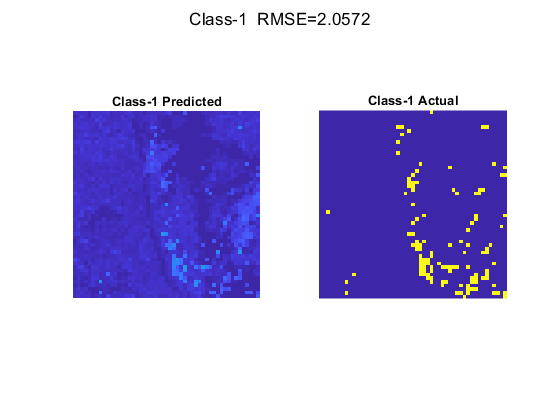

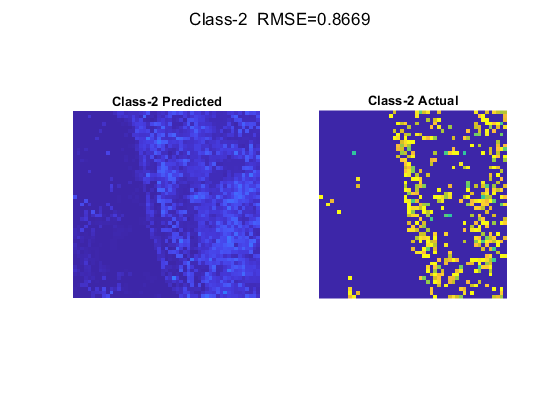

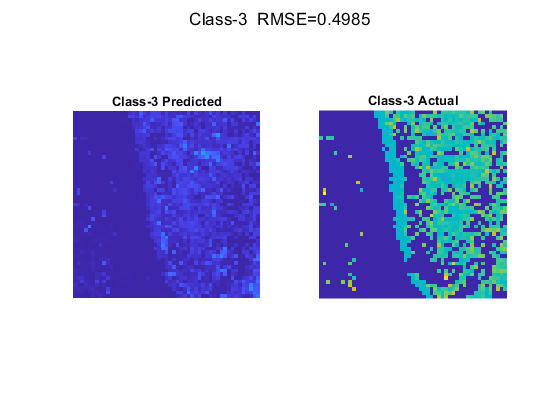

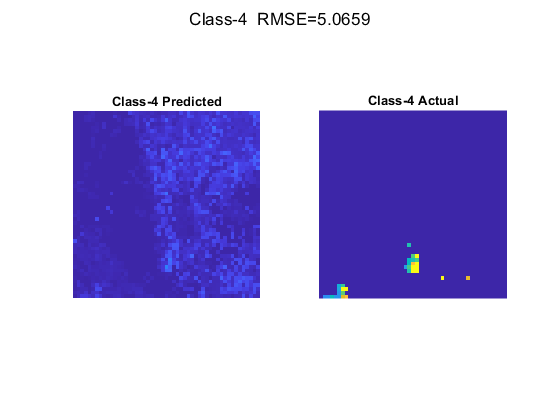

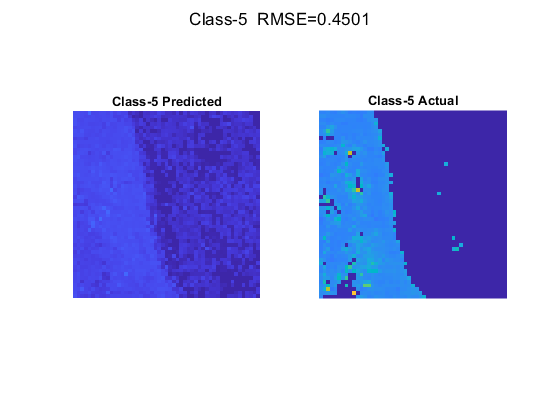

disp('ACTUAL VS PREDICTED FOR Data_10.h5:')
for j=1:5
    
    True = True_10(j,:)/mean(True_10(j,:));%Normalized 
    Predict = Predict_10{j}/mean(Predict_10{j});%Normalized 
    
    %Root Mean Squared Error
    error = round(sqrt(sum((True-Predict).^2)),2);
    
    figure
    sgtitle(append('Class-',num2str(j),'  RMSE=',num2str(error)))
    
    subplot(1,2,1)
    imshow(reshape(max(Predict_10{j},0),51,51),colormap);
    title(strcat('Class-',num2str(j),' Predicted'))
  
    subplot(1,2,2)
    imshow(reshape(True_10(j,:),51,51),colormap);
    title(strcat('Class-',num2str(j),' Actual'))
end

## Conclusion

We were successfully able to predict a few images for the different classes of data_10.h5. As we can see Root Mean Squared Error for few of the classes is not as less as desired exceeding 1 as the data fed into the model was not actually sequential but assumed to be so as explained at the starting. With proper sequential data we would be able to predict the (t+1) images successfully using this model.